clear all;

## Onset Conditions

dimension:

N=1500;
% correlation paramter:
eta=1;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=10;
% Delta t:
Dt=0.002;
% Temperature: Increase it!!!
T=5.0;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

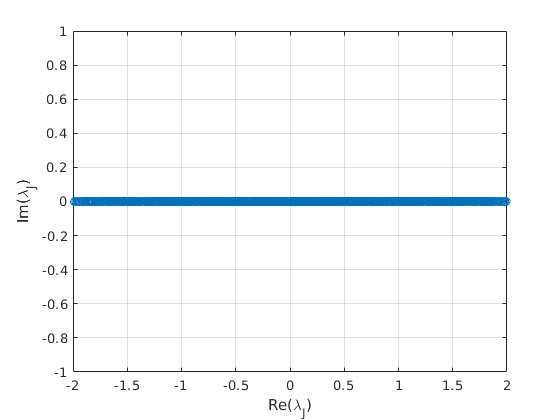

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## Run Dynamics

N_iter=tot_time/Dt;
tic
for i=2:N_iter
        z=randn(N,1)*sqrt(2*Dt*T);
        f=Dt*J*x(:,i-1)+z;
        x_norm=norm(x(:,i-1))^2;
        %x_norm=N;
        xf=x(:,i-1)'*f;
        x(:,i)=x(:,i-1)*(-xf/x_norm+sqrt((xf/x_norm)^2+(N-norm(f)^2)/x_norm))+f;
end
toc

Elapsed time is 32.051775 seconds.


figure()
%histogram of position for one spin
bin_edge=linspace(min(x(:)),max(x(:)),50);
H=0;
for i=1:size(x,1)
    [h,b]=histcounts(x(:,i),bin_edge);
    H=H+h;
end

Index exceeds matrix dimensions.

normalisation=sum(H)*(bin_edge(2)-bin_edge(1));
plot((bin_edge(1:end-1)+bin_edge(2:end))/2,H/normalisation,'-o')
hold on
spins=(bin_edge(1:end-1)+bin_edge(2:end))/2;
prob=exp(-spins.^2/2);
plot(spins,prob/sum(prob)/(bin_edge(2)-bin_edge(1)),'-.')

I compute  $\langle x_t x_{t'}\rangle=\frac{1}{N}\sum_{i=1}^N x_{i,t}x_{i,t'}$ i.e. I average over the different realisation of the spins.

%Uldis method, is too slow
figure()
y=x(:,2001:end);
corr=0

corr =      0


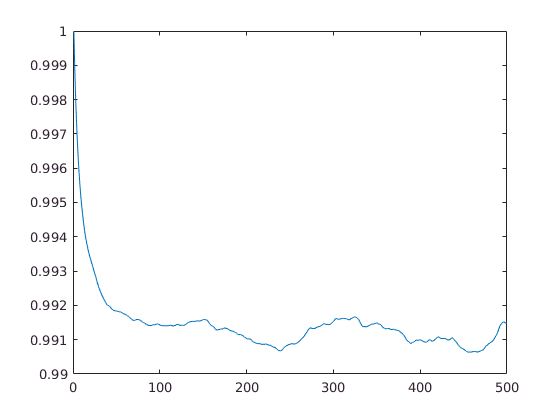

for tau=1:length(y)/2
    corr(tau)=mean(mean(y(:,tau:end).*y(:,1: end-tau+1)));
end
plot(corr)

% this is the fastest way to compute the correlation function
figure()
%t_wait=N^(2/3)/(1-T);
t_wait=0.1;
y=x(:,round(t_wait/Dt):end);% wait for thermalisation
t=round(size(y,2)/2);% this is the maximum time to observe a correlation
corr=0;
for i=1:size(y,1)
    corr=corr+xcorr(y(i,:),t,'unbiased');
end
corr=corr(ceil(end/2):end);

plot((1:length(corr))*Dt,corr/N,'DisplayName','Correlation')
%xlim([0,10]);
ylim([-0.05,1])
hold on
plot([0,5],[0,0],'--','DisplayName','q=0')
hold off
lg=legend('show')

lg =   Legend (Correlation, q=0) with properties:

         String: {'Correlation'  'q=0'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.67083 0.8123 0.21071 0.082143]
          Units: 'normalized'

  Show all properties


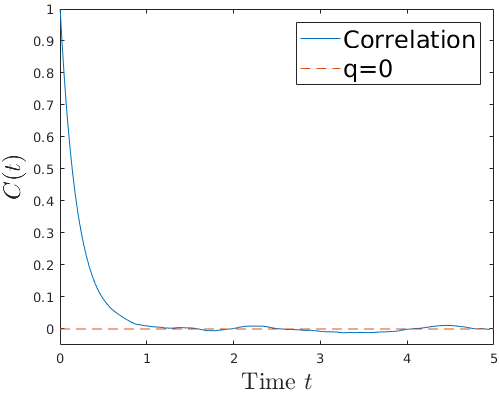

ans =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 498.63 396.8]
       Units: 'pixels'

  Show all properties


lg.FontSize=18;
xlabel('Time $t$','Interpreter','latex','FontSize',18)
ylabel('$C(t)$','Interpreter','latex','FontSize',18)
tightfig()

lg =   Legend (Correlation function, 1-T) with properties:

         String: {'Correlation function'  '1-T'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 16
       Position: [0.41012 0.75992 0.47143 0.13452]
          Units: 'normalized'

  Show all properties


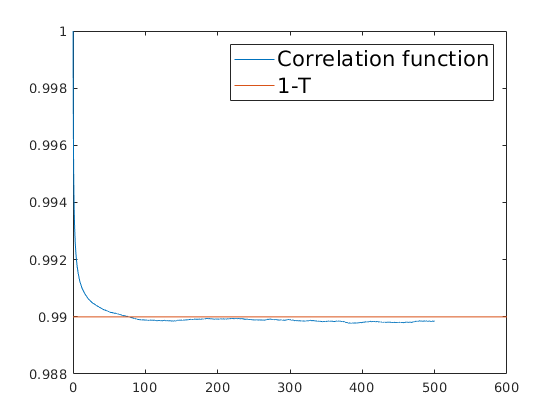

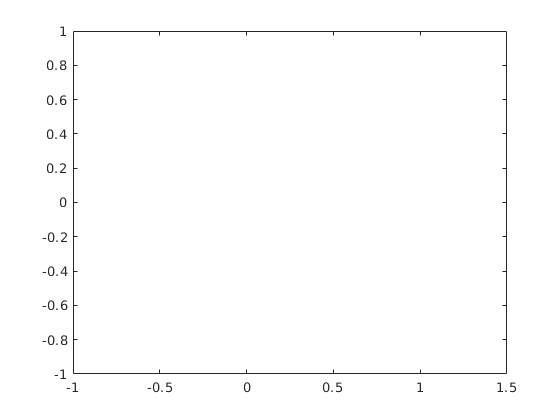

figure()
corr=0;
%hold on

for i=1:size(x,1)
    %corr=mean(x
    %corr=corr+xcorr(x(i,:),'unbiased');
end
corr=corr/N;
%hold off
figure()
plot((1:length(corr))*Dt,corr)

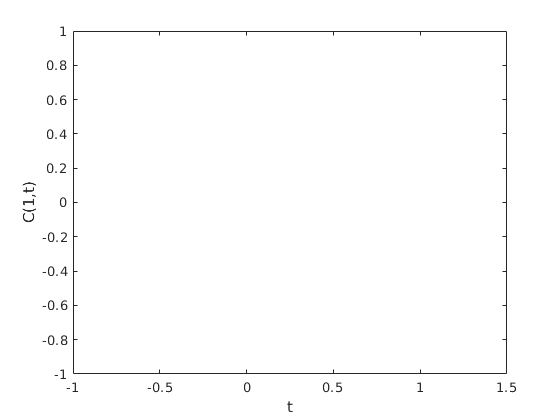

c=corr((end+1)/2:end);
plot((1:length(c))*Dt,c)
xlabel('t')
ylabel('C(1,t)')


% Fourier transfrorm of correlation function
P2=abs(fft(corr));
P1=P2(1:(end+1)/2+1);

Index exceeds matrix dimensions.

P1(2:end-1) = 2*P1(2:end-1);
f = 1/Dt*linspace(0,0.5,N_iter);
plot(f,P1(1:end-1))

